# Carbon Neutral

[⇦ Return to the navigation page](matlab:open('./Navigation.mlx'))

The challenge of climate change encourages companies, such as MathWorks, to commit themselves to becoming carbon neutral. This effort leads to using renewable energy to power the company's facility. In this script, we will explore two sources of renewable energy: hydropower and wind turbines. We will apply the conservation of mass, momentum, and energy to understand how this renewable energy source work and how much power it can power.

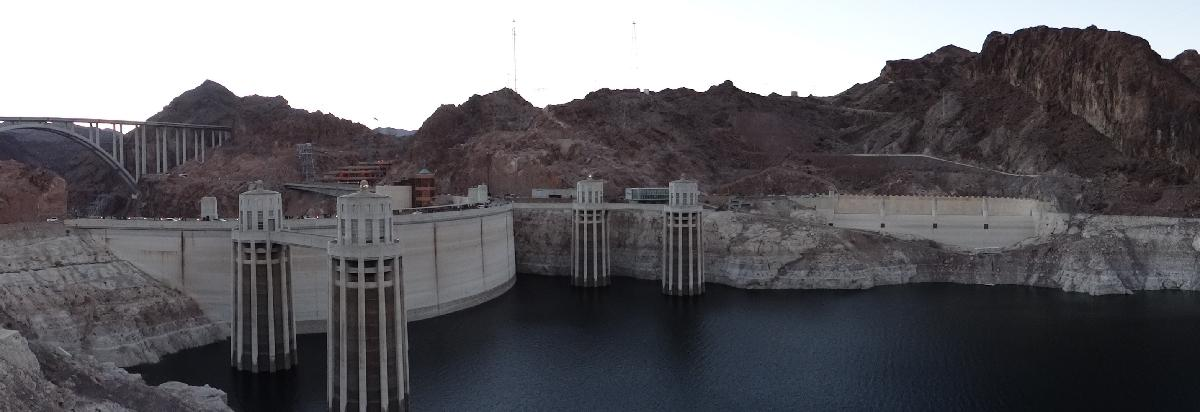

Hoover Dam intake tower from Lake Mead, [USGS](https://www.usgs.gov/media/images/hoover-dam-intake-towers-panorama)

## Energy in a fluid

In a fluid, energy refers to the ability of a fluid to produce work. It takes various forms:

- Kinetic energy refers to the energy of motion.

- Potential energy refers to the energy associated with external fields such as gravity.

- Internal energy refers to the molecular internal energy of the fluid.

  **Try. **Following the prompt from `unitInfo`, explore all units of energy available.

unitInfo("Energy")


All units of dimension 'Power':

HP_DIN - metric horsepower (DIN 66036)
HP_E - electrical horsepower
HP_I - mechanical horsepower
HP_UK - British imperial horsepower
poncelet - poncelet
PS_DIN - horsepower (DIN 70020)
PS_SAE - net horsepower (SAE J1349)
W - watt ['SI']

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



Just as the mass is often studied by considering the density (mass per unit of volume), we are often exploring the energy in the fluid by considering the specific energy  $e$ (energy per unit of mass):


$$e=\frac{V^2}{2}+gz+u$$


Where $e$ is the specific energy, $V$ is the velocity, $g$ is the local acceleration due to gravity, $z$ is the elevation and $u$ is the specific internal energy as defined in thermodynamics. You should check out the [thermodynamics module](https://www.mathworks.com/matlabcentral/fileexchange/126784-thermodynamics)to learn more about internal energy. The conservation of energy can be derived from the first law of thermodynamics:

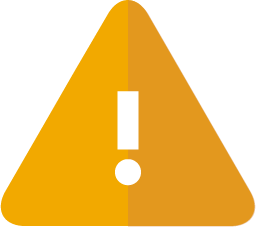  This expression might look different from what you have seen in your textbook and lectures. **In this script, we use the letter** $V$ **to denote velocities, **$z$ **elevation, and **$u$ **internal energy.** These letters are often used to represent other metrics. For example, V is commonly used for volume and  is also used for velocity.

From the first law of thermodynamics, we can derive the conservation of energy over the control volume:


$$\frac{\partial}{\partial t}\int_{\Omega =CV} \rho e\; d\Omega + \int_{\Gamma=CS} (\vec{V}\cdot\vec{n})\rho e\;d\Gamma=\dot{Q}-\dot{W}$$


Where $\vec{n}$ is the normal vector to the surface, $\rho$ is the mass density, $e$ is the specific energy, $\vec{V}$ is the velocity vector, $\dot{Q}$ is the rate of heat exchanged with the surrounding, $\dot{W}$ is the rate of exchanged work with the surrounding, $d\Omega$ and $d\Gamma$ respectively represent the infinitesimal integration volumes and surfaces.

  **Pro-tip**. Dimensional analysis can help you verify what the term in the equation represents:


$$\int_{\Omega =CV} \rho e\; d\Omega $$


The $[\;\;]$ operator is used the denote the units:


$$\left[\int_{\Omega =CV} \rho e\; d\Omega \right] = \left[\rho\right]\left[e\right]\left[d\Omega\right]$$


We know that:

- 
$$[\rho] = \text{kg}\cdot\text{m}^{-3}$$


- 
$$[e] = \text{J}\cdot\text{kg}^{-1}$$


- 
$$[d\Omega]=\text{m}^3$$


Therefore,


$$\left[\int_{\Omega =CV} \rho e\; d\Omega \right] = \text{kg}\cdot{m}^{-3}\cdot\text{J}\cdot\text{kg}^{-1}\cdot\text{m}^3=\text{J}$$


## Power in a fluid

Power refers to the rate at which energy is transferred and can be expressed as energy per unit of time. In the energy conservation equation, the term $\dot{Q}$ and $\dot{W}$ are examples of powers. It is typically measured in units of energy per unit of time, such as Watts (W) or horsepower (hp).

  **Try. **Following the prompt from `unitInfo`, explore all units of pressure available.

unitInfo("Power")

## Problem Statement

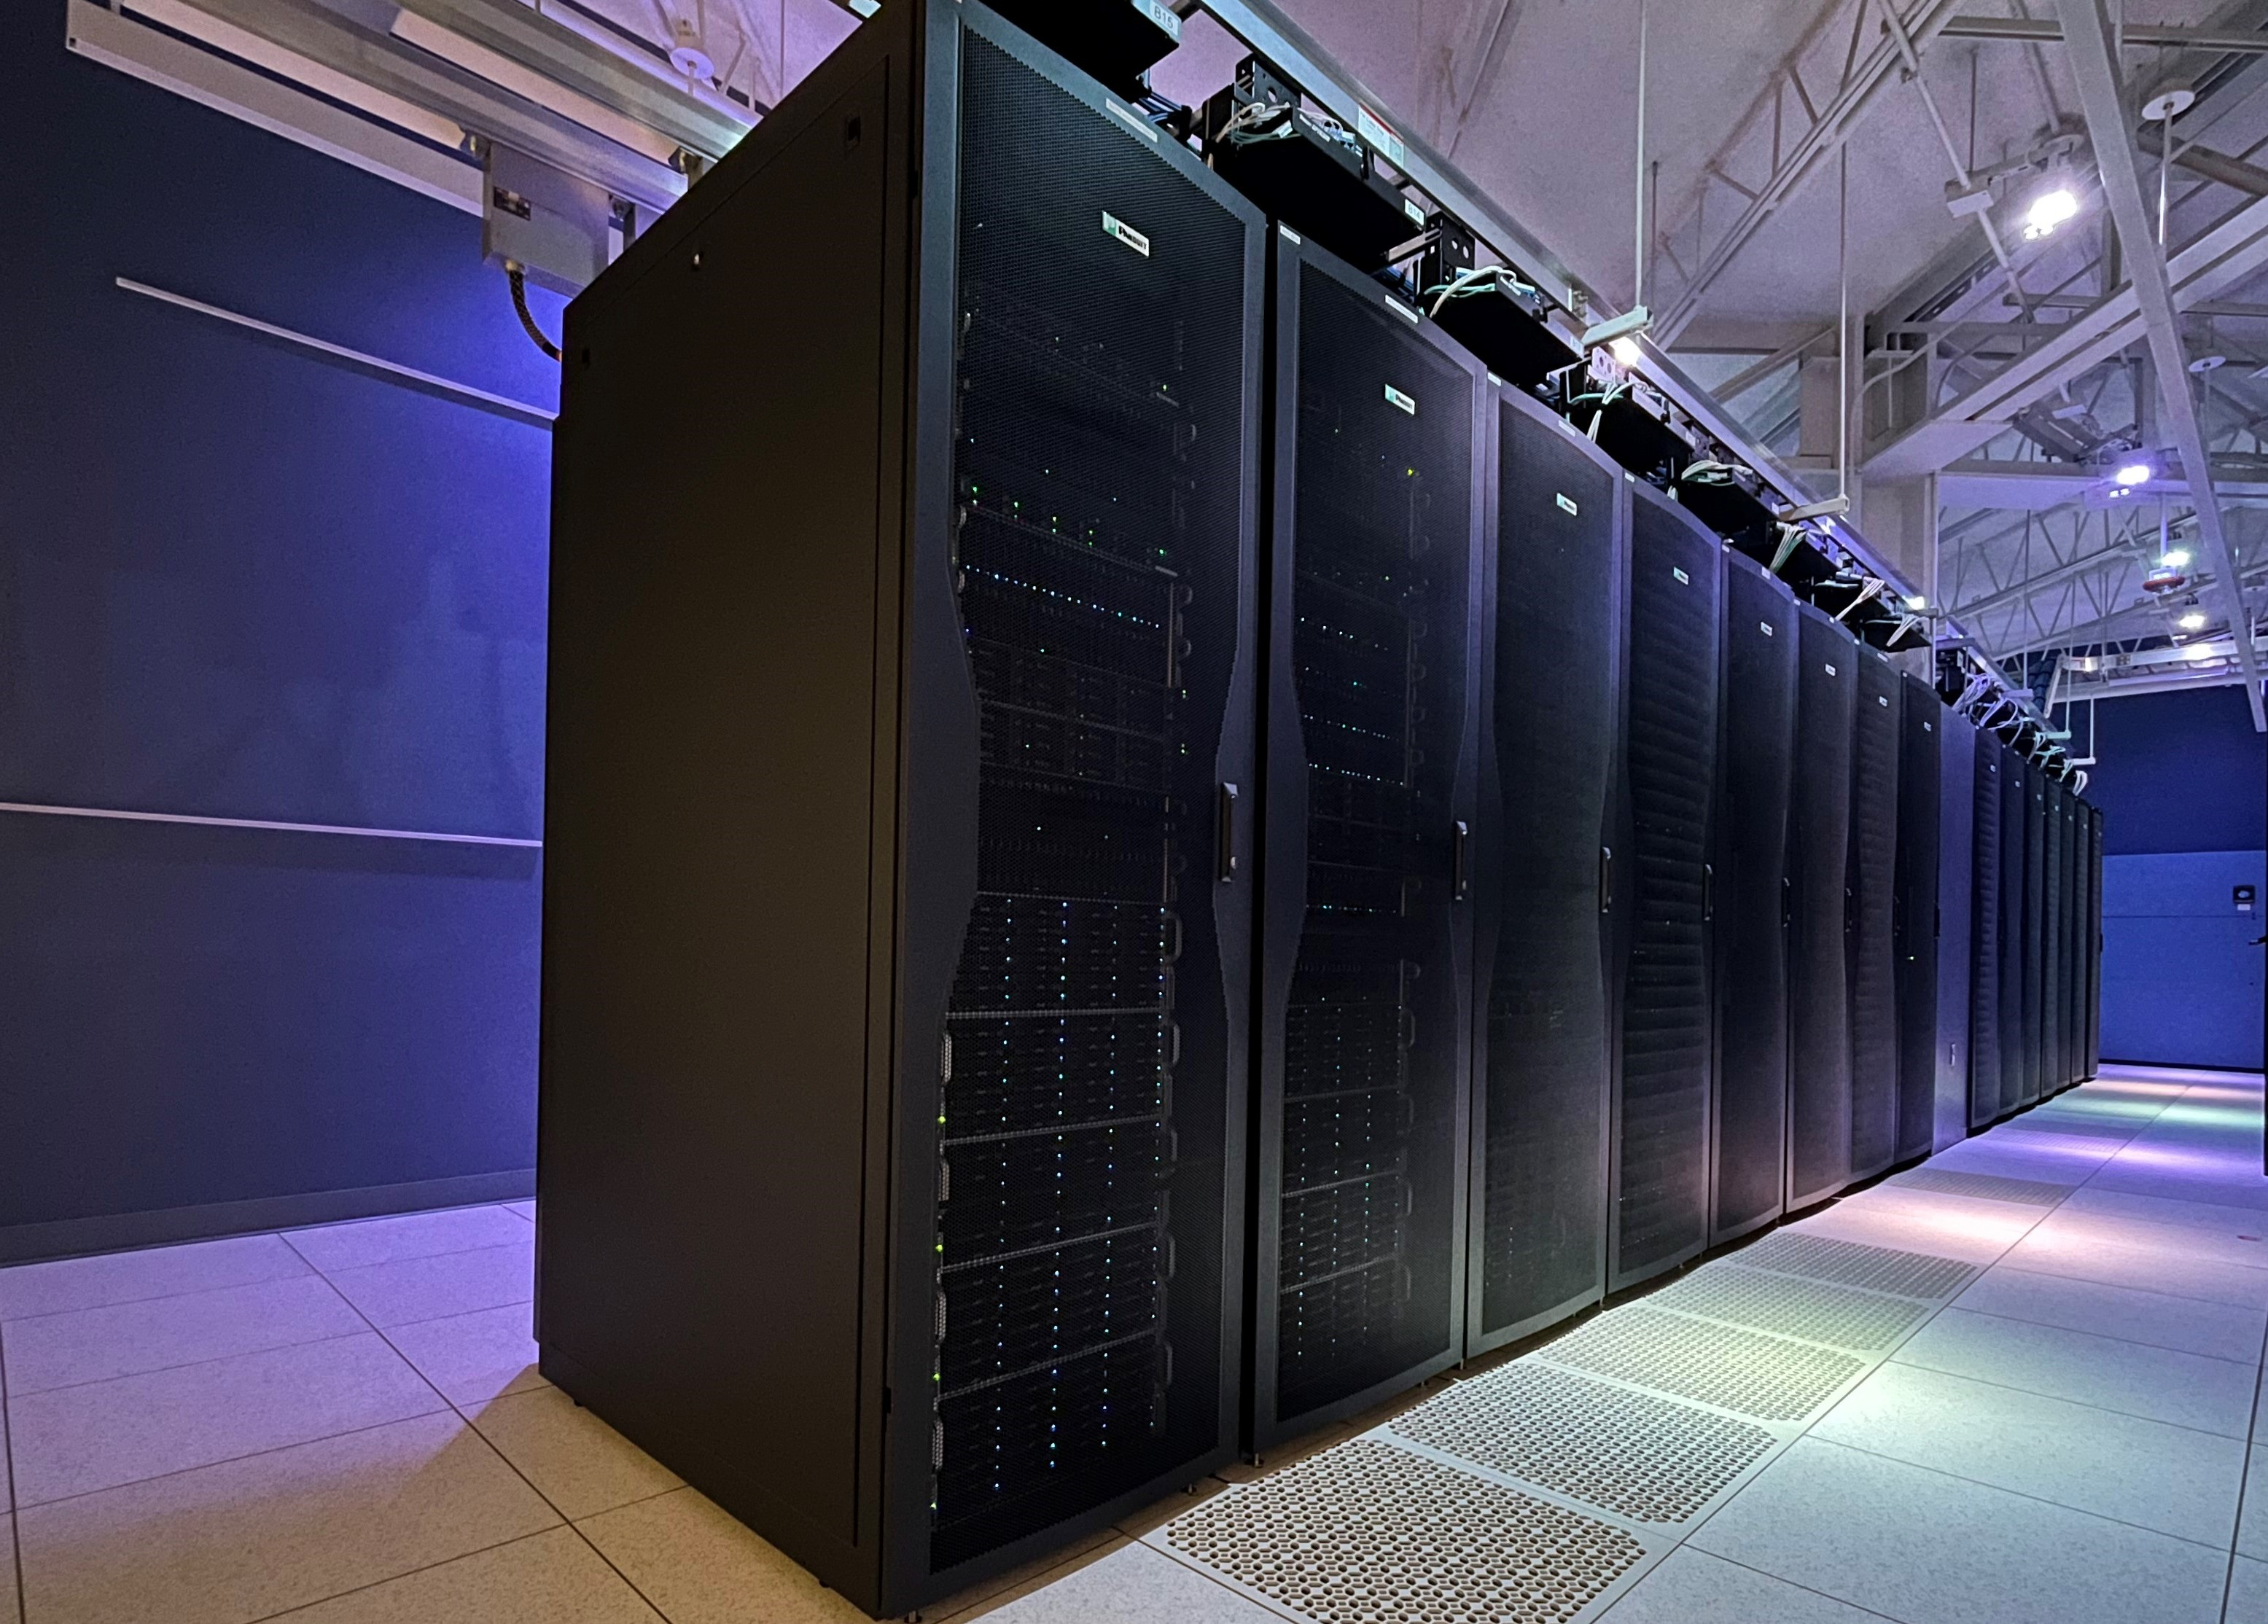

MathWorks pledged to become [carbon neutral by 2023](https://www.mathworks.com/company/aboutus/carbon-neutral.html). One of the major energy consumptions of its headquarters in Natick, MA, is a data center. In this script, we will study the possibility of offsetting this power consumption by generating renewable energy with wind turbines or hydropower. We will assume that the data center’s maximum power consumption is 1300 kW. 

 The data presented in this script are fictional and do not represent the actual power consumption by the MathWorks data center.

  **Try. **Load the data center electrical consumption data.

dataCenter = 12×1 timetable
       date        electricalConsumption
    ___________    _____________________
    01-Jan-2022         3.7721e+05      
    01-Feb-2022         3.6691e+05      
    01-Mar-2022         3.7721e+05      
    01-Apr-2022         3.4632e+05      
    01-May-2022         4.4491e+05      
    01-Jun-2022         4.3056e+05      
    01-Jul-2022         5.2229e+05      
    01-Aug-2022         4.6426e+05      
    01-Sep-2022          4.212e+05      
    01-Oct-2022         3.4819e+05      
    01-Nov-2022          3.276e+05      
    01-Dec-2022         3.4819e+05      

load DataCenter.mat
dataCenter

The electrical consumption from the data center is reported for every month of 2022, but what are those numbers referring to (energy? power?), and what unit are they expressing in?

  **Try. **Check the units used in this table.

 

% Display the unit in registered in the table:
electricalConsumptonUnit = dataCenter.Properties.VariableUnits

electricalConsumptonUnit = 1×1 cell array
    {'kWh'}

% Transform the string representing the unit into a symbolic unit:
electricalConsumptonUnit = str2symunit(electricalConsumptonUnit);

  **Try.** Plot electrical consumption over the year.

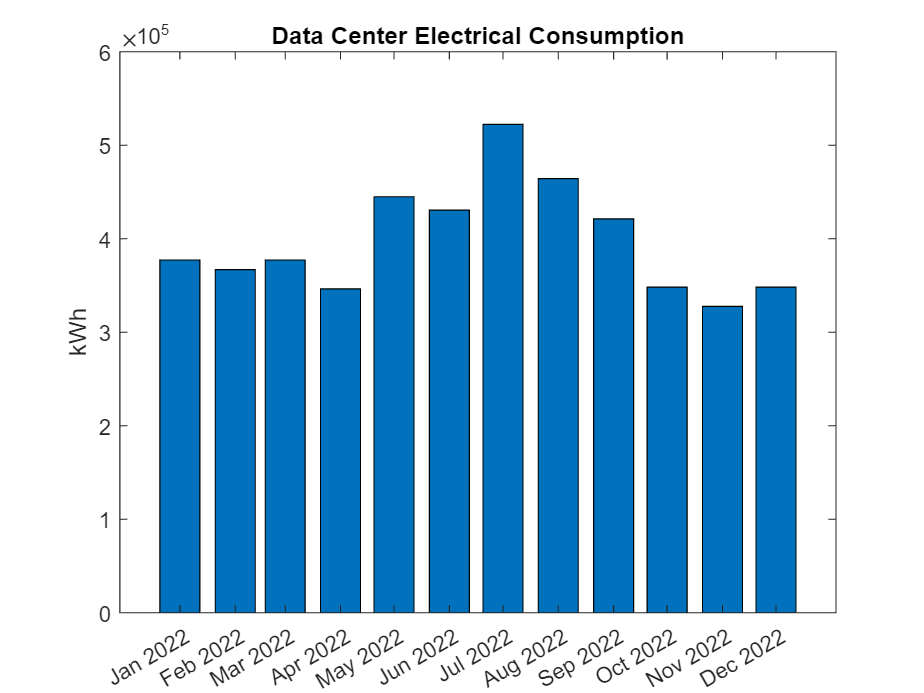

 
bar(dataCenter.date,dataCenter.electricalConsumption)
ylabel(symunit2str(electricalConsumptonUnit))
title("Data Center Electrical Consumption")

 **Exercise. **Is the electrical consumption an energy measurement or a power measurement?

checkElectricalConsumptionDimension(1)

Good job! 'kWh' is indeed a unit of energy.


 **Exercise. **Calculate the total electrical energy consumed by the data center in 2022.

% Your code goes here:
totalElectricalComsumption = sum(dataCenter.electricalConsumption);

% Display the results with the associated unit retrieved earlier:
totalElectricalComsumption = totalElectricalComsumption * electricalConsumptonUnit

$$totalElectricalComsumption = 4774848\,\mathrm{kWh}$$

  CheckAnnualEnergyConsumpion(totalElectricalComsumption)

Good job! You computed the total annual energy consumption correctly.


 **Reflect**. As a comparison, a laptop consumes around 200 kWh per year.

## Scenario 1: wind turbines

We are now considering offsetting the energy consumption calculated in the previous section by installing wind turbines near Natick, MA’s headquarters. Wind turbines generate electricity by collecting energy from incoming wind and slowing it down.

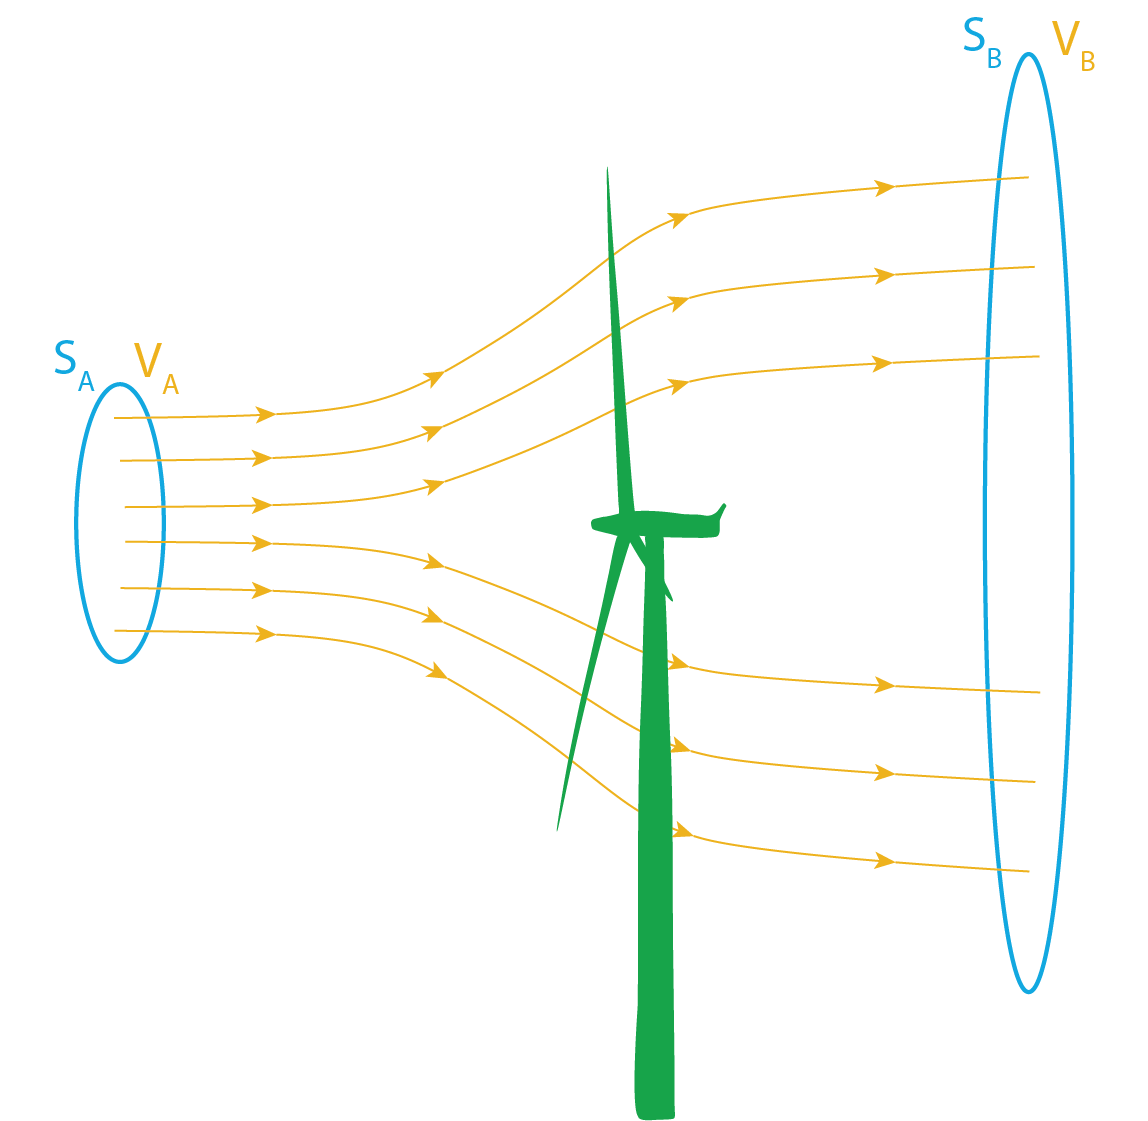

A power turbine with surface area $S_T$, generates power by collecting the kinetic energy from upstream airflow at velocity $V_A$ (m/s). The airflow is slowed down and exits the system downstream at velocity $V_B$. The wind speed at the turbine is $V_T$. 

### **Control Volume Method**

This section applies the [control volume method](matlab:open('./ManOnTheMoon.mlx')) to the wind turbine. We are considering the control volume to include all the streamlines of fluid going through the turbine from the upstream disk A to the downstream disk B introduced in the previous figure.

#### **Mass Conservation**

All the mass flow coming in the control volume through surface A must exit the control volume through surface B. Therefore, we can write the following mass flow equilibrium:


$$\rho S_A V_A = \rho S_B V_B = \rho S_T V_T = \dot{m}$$


Where $\rho$ is the density,  $(S_A,S_B,S_T)$ are the areas of surfaces A, B, and the area of the turbine, and $(V_A,V_B,V_T)$ are the flow velocity through the surfaces A, B, and the turbine ($T$) itself.

  **Try. **Define the problem parameters (velocities, areas) and compute the mass flow through the turbine.

 
syms rho S_A S_B S_T V_A V_B V_T
massFlow = rho*S_T*V_T

$$massFlow = S_{T}\,V_{T}\,\rho$$

The variable `massFlow `represents the mass flow denoted $\dot{m}$ in the previous equation.

#### **Momentum Conservation**

The momentum conservation equation can be expressed as:


$$\underbrace{\frac{\partial}{\partial t}\int_{\Omega=CV}\rho\vec{V} \; d\Omega}_\text{Acceleration}
+
\underbrace{\int_{d\Gamma=CS}(\vec{V}\cdot\vec{n})\rho\vec{V} \; d\Gamma}_\text{Thrust}
=
\sum\vec{F}$$


Where $\rho$ is the mass density, $\vec{V}$ is the velocity vector and $\vec{F}$ is the force applied to the control volume. We consider the flow to be steady, so the derivative with respect to time is equal to zero. There is no radial flow, so all the air entering the turbine upstream exits the turbine downstream. Therefore, we are left with the following:


$$\int_\text{\Gamma=\text{disk A}}(\vec{V_A}\cdot\vec{n_A})\rho\vec{V_A} \; d\Gamma
+
\int_\text{\Gamma=\text{disk B}}(\vec{V_B}\cdot\vec{n_B})\rho\vec{V_B} \; d\Gamma
=
\vec{F}_\text{turbine\rightarrow air}$$


We are projecting the equation along $\vec{e_x}$, the basis vector along the horizontal axis oriented from left to right:


$$\int_\text{\Gamma=\text{disk A}}(\vec{V_A}\cdot\vec{n_A})\rho\vec{V_A}\cdot\vec{e_x} \; d\Gamma
+
\int_\text{\Gamma=\text{disk B}}(\vec{V_B}\cdot\vec{n_B})\rho\vec{V_B}\cdot\vec{e_x} \; d\Gamma
=
\vec{F}_\text{turbine\rightarrow air}\cdot\vec{e_x}$$


Therefore,


$$\int_\text{\Gamma=\text{disk A}}(\vec{V_A}\cdot\vec{n_A})\rho V_A \; d\Gamma
+
\int_\text{\Gamma = \text{disk B}}(\vec{V_B}\cdot\vec{n_B})\rho V_B \; d\Gamma
=
F_\text{turbine\rightarrow air}$$


Thus,


$$-\dot{m}V_A+\dot{m}V_B=F_\text{turbine\rightarrow air}=-F_T$$


With $F_T$ being the force of the force acting on the turbine.

 **Exercise. **Using the variable `massFlow` corresponding the $\dot{m}$ and the symbolic variable `V_A` and `V_B`, express the force acting on the turbine.

% Your code goes here:
F_T = massFlow*(V_A-V_B)

$$F\_T = S_{T}\,V_{T}\,\rho \,\left(V_{A}-V_{B}\right)$$


  checkForceAirOnTurbine(F_T)

Good job! The force acting on the turbine correctly!


From the force acting on the turbine, we can compute the energy that is extracted from the wind using the following relation:


$$dW = \vec{F} \cdot\vec{d x}$$


Where $dW$ is the small amount of work that occurs over an instant $dt$, $\vec{F}$ is the force, and $\vec{dx}$ is air displacement during that instant $dt$. The displacement $\vec{dx}$ can be expressed as:


$$\vec{dx} = \vec{V}dt$$


Where $\vec{V}$ iis the velocity vector. In the case of our turbine, we can estimate that the small amount of work on the turbine  ($dW_T$) during an instant $dt$ is:

 
$$dW_T = F_T \cdot V_Tdt$$


Where $F_T$ is the force acting on the turbine and $V_T$ the velocity at the turbine. We can now estimate the power extracted by the turbine ($P_T$) as the derivative of the work with respect to time:


$$P_T=\frac{dW_T}{dt}$$



$$P_T=\frac{F_TV_Tdt}{dt}=F_TV_T$$


 **Exercise. **Compute the power of the collected by the turbine.

P_T = F_T*V_T

$$P\_T = S_{T}\,{V_{T}}^{2}\,\rho \,\left(V_{A}-V_{B}\right)$$

  checkPowerTurbine(P_T)

Good job! You calculated the power at the turbine correctly.


#### Energy conservation

Finally, we can consider the energy conservation equation:


$$\frac{\partial}{\partial t}\int_{\Omega =CV} \rho e\; d\Omega + \int_{\Gamma=CS} (\vec{V}\cdot\vec{n})\rho e\;d\Gamma=\dot{Q}-\dot{W}$$


Where, $e$ is the specific energy, $\dot{Q}$ is the rate of thermal energy brought to the system and $\dot{W}$ is the rate of work. Similarly to the previous calculation, the wind turbine is considered at steady state. Therefore, the derivative with respect to time is equal to zero. All of the fluid entering disk A, exit through disk B and there is no radial flow, therefore:


$$ \int_{\Gamma=\text{disk A}} (\vec{V_A}\cdot\vec{n})\rho e_A\;d\Gamma 
+
 \int_{\Gamma=\text{disk B}} (\vec{V_B}\cdot\vec{n})\rho e_B\;d\Gamma 
=-\dot{W}_{\text{air}\rightarrow\text{turbine}}$$


We are using the same notation introduced earlier. The rate of work is equivalent to the power of the turbine $P_T$:


$$-P_T
=
 \int_{\Gamma=\text{disk A}} (\vec{V_A}\cdot\vec{n})\rho e_A\;d\Gamma 
+
 \int_{\Gamma=\text{disk B}} (\vec{V_B}\cdot\vec{n})\rho e_B\;d\Gamma 
$$



$$P_T
=
 \int_{\Gamma=\text{disk A}} \rho V_A e_A\;d\Gamma 
-
 \int_{\Gamma=\text{disk B}} \rho V_Be_B\;d\Gamma 
$$


The specific energy of the air at disks A and B can be expressed as:

- $e_A = \frac{V_A^2}{2}+gz_a+u_A$    with $z_A$ the elevation at disk A and $u_A$ the air internal energy at disk A

- $e_A = \frac{V_B^2}{2}+gz_B+u_B$    with $z_B$ the elevation at disk B and $u_B$ the air internal energy at disk B

The local variation of elevation in disks A and B is neglected ($z_A = z_B$). The air internal energy is considered equal at disks A and B ($u_A = u_B$). After integration we obtain:


$$P_T
=
\dot{m}\left(\frac{V_A^2}{2}+g z_A + u_A \right)
-
\dot{m}\left(\frac{V_B^2}{2}+g z_B + u_B \right)
$$



$$P_T
=

\dot{m}\left(\frac{V_A^2}{2}+g z_A + u_A  - \frac{V_B^2}{2} - g z_B - u_B \right)
$$



$$P_T
=
\frac{1}{2} \dot{m} (V_A^2-V_B^2)
$$


This is a different expression than the one obtained previously. However, both equations should be satisfied:


$$F_T V_T
=
\frac{1}{2} \dot{m} (V_A^2-V_B^2)
\qquad (\spadesuit)$$


 **Exercise. **Define the equation $(\spadesuit)$ in the `powerEquality` variable using the `==` operator.

% Your code goes here:
powerEquality = F_T*V_T == 0.5*massFlow*(V_A^2-V_B^2)

$$powerEquality = S_{T}\,{V_{T}}^{2}\,\rho \,\left(V_{A}-V_{B}\right)=0.5000\,S_{T}\,V_{T}\,\rho \,\left({V_{A}}^{2}-{V_{B}}^{2}\right)$$


 checkPowerEquality(powerEquality)

Good job! You defined the power equality correctly.


 **Exercise. **Solve the equation $(\spadesuit)$ in order to express $V_T$ as a function of the other parameters of the problem. Store the solutions of the equation in solV_T

solV_T = solve(powerEquality,V_T)

$$solV\_T = \left(\begin{array}{c} 0\\ 0.5000\,V_{A}+0.5000\,V_{B} \end{array}\right)$$


 checkVelocitySoln(solV_T)

Good job! You solve the equation correctly.


 **Reflect**. There is two solutions to the previous equation. However, physically only one should make sense.

 **Exercise. **Substitute the right solution of the previous equation in the expression of the power extracted by the turbine `P_T`.

% Your code goes in the next line:
P_T = subs(P_T,V_T,solV_T(2))

$$P\_T = S_{T}\,\rho \,{\left(0.5000\,V_{A}+0.5000\,V_{B}\right)}^{2}\,\left(V_{A}-V_{B}\right)$$


 checkPowerTurbine2(P_T)

Good job! You found the expression of the power collected as a functionof the upstream and downstream velocity.


The power collected by the turbine is now a function of the upstream and downstream velocity.

### Wind turbine efficiency

The efficiency can be expressed as the ratio between the power collected by the turbine over the maximum power available to the turbine $\eta = \frac{P_T}{P_\text{max}}$. The maximum available to the turbine should be equal to the wind's power going to the turbine's surface if the turbine still needs to be built. This maximum power could be estimated using the following relation:


$$P= \rho S\frac{V^3}{2}$$


Where, $\rho$ is the mass density, $S$ is the disk's surface, $V$ is the wind speed. Now, we must select the right $S$ and $V$ out of the parameters of the problem: $S_A$, $S_B$, $S_T$, $V_A$, $V_B$ and $V_T$.

 **Exercise. **Using the relation, we defined, calculated the maximum power, and saved the results in  `P_max`.

% Your code goes here:
P_max = 0.5*rho*S_T*V_A^3

$$P\_max = 0.5000\,S_{T}\,{V_{A}}^{3}\,\rho$$

 
 checkMaximumPower(P_max)

Good job! You defined the maximum to be collected by the turbine correctly.


 **Exercise. **Define the turbine's efficiency $\eta$ in `eta_T` as a function of `P_T` and `P_max`.

% Your code goes here:
eta_T = P_T/P_max

$$eta\_T = \frac{2\,{\left(0.5000\,V_{A}+0.5000\,V_{B}\right)}^{2}\,\left(V_{A}-V_{B}\right)}{{V_{A}}^{3}}$$


 checkTurbineEta(eta_T)

Good job! You defined the turbine efficiency correctly.


The power efficiency of the wind turbine only depends on two parameters, the upstream velocity $(V_A)$ and downstream velocity $(V_B)$. We introduced a single parameter $x = \frac{V_B}{V_A}$. This parameter corresponds to how much the wind is slowed down by the wind turbine.

  **Try. **Run the following lines of code to express the turbine’s efficiency as a function of the parameter $x$.

syms x
eta_T = simplify(subs(eta_T, V_B, x*V_A))

$$eta\_T = -0.5000\,\left(x-1\right)\,{\left(x+1\right)}^{2}$$

The expression of the turbine efficiency is now a function of a single parameter $x$. 

  **Try. **Plot the wind turbine efficiency as a function of the parameter $x$.

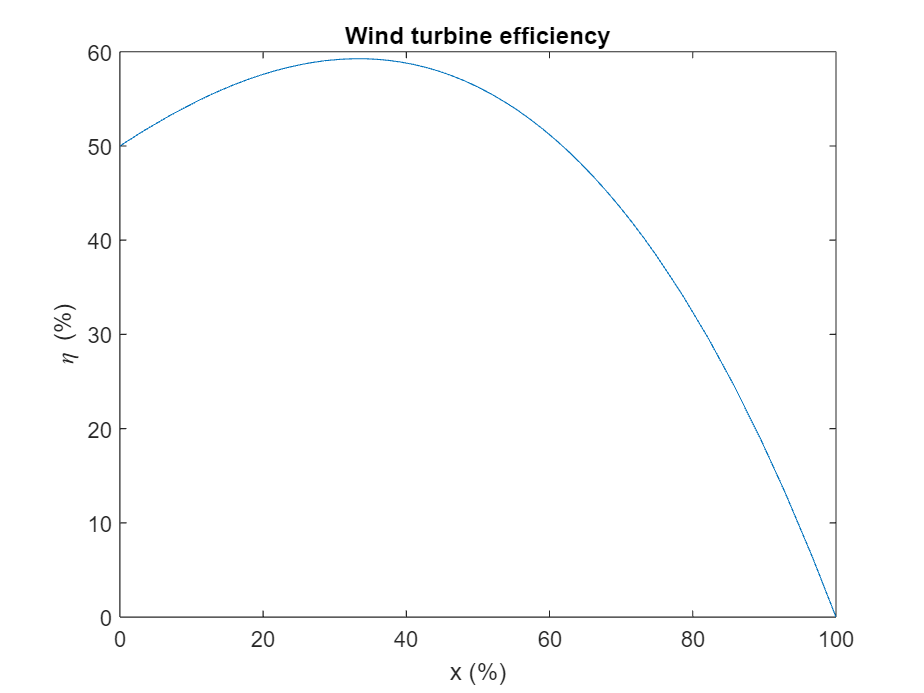

% Plotting function
fplot(100*x,100*eta_T,[0 1])
xlabel("x (%)")
ylabel("\eta (%)")
title("Wind turbine efficiency")

 **Reflect**. Does the wind turbine's efficiency have a maximum?

 **Reflect**. Can you collect all the power available from the wind?

 **Reflect**. Why are we only plotting the solution with $x$ from 0 to 100%? What would it means to have a negative $x$ or $x$ greater than 100%?

  **Try.** Run the following code to determine the maximum efficiency of the turbine.

deta = diff(eta_T,x);
xmax = solve(deta == 0,x);
if xmax~=0
    xmax = max(xmax);
end

eta_max = subs(eta_T,x,xmax)

$$eta\_max = 0.5926$$

### Estimate impact of wind turbine farm

We just computed the maximum functioning efficiency of a wind turbine. We want to estimate how much energy could be collected in a specific location. We retrieve data from a [connected weather station](https://www.mathworks.com/matlabcentral/fileexchange/47049-analyzing-weather-data-from-an-arduino-based-weather-station?s_tid=srchtitle_weather%20station_1) in Natick, MA. Now that we know how much energy can be extracted by a wind turbine, $\eta_{\text{max}}$, we can use the Natick wind data to determine the energy a wind turbine could collect in this location.

Now that we know how much energy can be extracted by a wind turbine, we can use weather data from a weather station in Natick, MA, to determine the energy a wind turbine could collect in this location.

  **Try.** Load and visualize the weather data.

 
load NatickWeather.mat
weather

weather = 365×5 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint
    ___________    ________    _______    ______    ________    ________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381 
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752 
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912 
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403 
    05-Jan-2022      3.0132     1.8485    89.962     6.4262      1.0056 
    06-Jan-2022      1.9187     1.4706    73.631          0     -3.3551 
    07-Jan-2022     -2.2704      1.632    85.014          0     -5.

  **Try.** Again, we can check the units in the timetable.

 
weather.Properties.VariableUnits

ans = 1×5 cell array
    {'Celsius'}    {'m/s'}    {0×0 char}    {'mm'}    {'Celsius'}

  **Try.** The air density at sea level is estimated to be 1.2 $\text{kg}\cdot\text{m}^{-3}$, and the diameter of the turbine rotor disk can be defined using the following slider.

units = symunit;
D_T = 65* units.m;
S_T = pi*D_T^2/4;
rho = 1.2*units.kg/units.m^3;

The maximum efficiency of a wind turbine computed in the previous section was below 60%. This efficiency is not considering the electrical and mechanical efficiency of the system. Most wind turbine function at lower efficiency than the ideal maximum efficiency we defined. For the rest of this script, we will consider the global efficiency of the system is  $\eta = 40\%$. The power maximum power to be extracted from the wind can be estimated as follows:


$$P_{max}=\frac{1}{2}\rho S_T V^3$$


and, 


$$\eta = \frac{P_\text{T}}{P_{max}}$$


 **Exercise. **Complete the following edit field to compute the turbine extracted by the turbine.

% Define the efficiency:
eta = 0.4;

% Your code goes here:
weather.powerExtracted =  eta*1/2*rho*S_T.*(weather.Wind*units.m/units.s).^3

weather = 365×6 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint            powerExtracted         
    ___________    ________    _______    ______    ________    ________    _______________________________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381     71.2525*(([kg]*[m]^2)/[s]^3)   
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752     1.0019e+03*(([kg]*[m]^2)/[s]^3)
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912     1.4946e+04*(([kg]*[m]^2)/[s]^3)
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403     4.2052e+03*(([kg]*[m]^2)/[s]^3)
    05-Jan-2

  checkPowerExtractedTurbine(weather,D_T)

Good job! The power corrected was defined correctly.


  **Try.** Based on your previous answer, we can compute the energy generated each day, the annual energy production, and the number of wind turbines that would need to be installed to power the data center.

% Compute the daily and annual energy produced by the wind turbine
weather.dailyProduction = weather.powerExtracted * 1*units.day

weather = 365×7 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint            powerExtracted                       dailyProduction          
    ___________    ________    _______    ______    ________    ________    _______________________________    ___________________________________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381     71.2525*(([kg]*[m]^2)/[s]^3)       71.2525*(([d]*[kg]*[m]^2)/[s]^3)   
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752     1.0019e+03*(([kg]*[m]^2)/[s]^3)    1.0019e+03*(([d]*[kg]*[m]^2)/[s]^3)
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794    


% Sum over the daily production to compute the annual production
turbineAnnualProduction = sum(weather.dailyProduction)

$$turbineAnnualProduction = 3.1368e+06\,\frac{d\,\mathrm{kg}\,m^{2}}{s^{3}}$$

if turbineAnnualProduction ~= 0

    % Rewrite this energy in more common energy unit, kWh
    turbineAnnualProduction = unitConvert(turbineAnnualProduction, units.kWh)
    
    % Compute the number of wind turbine that would need to be installed
    numberOfTurbine = totalElectricalComsumption/turbineAnnualProduction

end

$$turbineAnnualProduction = 7.5282e+04\,\mathrm{kWh}$$

$$numberOfTurbine = 63.4261$$

 **Reflect**. How acceptable would it be to install this number of wind turbines in a suburban area such as Natick, MA?

## Scenario 2: Hydropower

The second option to power the MathWorks data center is to build a retention lake near the headquarters in Natick, MA. The water collected in this retention lake would be used to generate hydroelectricity. We are considering building a retention lake inspired by the [MATLAB logo](https://www.mathworks.com/help/matlab/visualize/creating-the-matlab-logo.html).

  **Try. **Visualize the design of the retention lake.

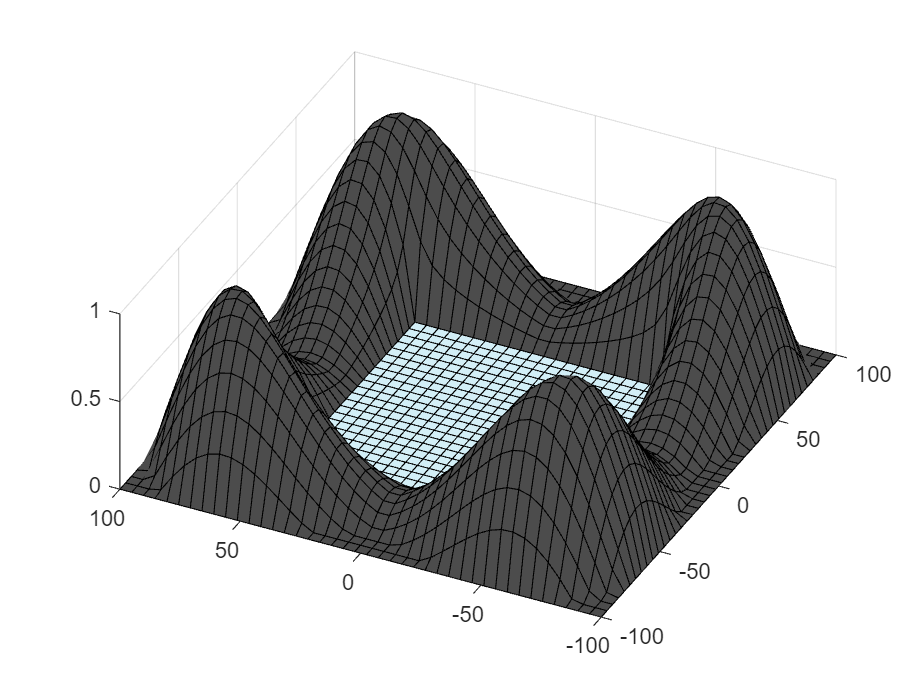

 
plotRetentionLake

### Creating a mathematical model

To model the power generated over a year by this installation, we will apply the conservation of mass to the control volume that is the lake. 


$$\displaystyle\frac{\partial}{\partial t}\int_{\Omega=CV}\rho \; d\Omega
+
\int_{\Gamma=CS} (\vec{V}\cdot\vec{n})\rho \; d\Gamma 
= 
0$$



$$\displaystyle\frac{\partial}{\partial t}\int_{\Omega=CV}\rho S_\text{lake} \; dh 
+ 
\int_{\Gamma=CS} (\vec{V}\cdot\vec{n})\rho \; d\Gamma
= 
0$$



$$\rho S_\text{lake}\frac{dh}{dt} 
+
\int_{\Gamma=CS} (\vec{V}\cdot\vec{n})\rho \; d\Gamma = 0$$



$$\rho S_\text{lake}\frac{dh}{dt} + \dot{m}_\text{rain} + \dot{m}_\text{evaporation} + \dot{m}_\text{turbine} = 0$$


Where $CV$ is the volume of water of the lake and $CS$ limit of the retention lake, $h$ is the water level of the lake, $S_{lake}$ is the area of the lake, $\rho$ is the mass density of water, ($\dot{m}_{rain}$, $\dot{m}_{evaporation}$, $\dot{m}_{turbine}$) represents the mass flow of water into the control volume from rain, evaporation and through the turbine. To ensure the sustainability of the water resource, we are considering that the retention lake should constantly keep the same water height, therefore   $\frac{dh}{dt} = 0$, and:


$$\dot{m}_\text{turbine} = - \dot{m}_\text{rain} - \dot{m}_\text{evaporation}$$


**Remark: **The different $\dot{m}$ are positive if the flow is leaving the control volume (*i.e., *the retention lake) and negative if the flow is entering the control volume. We can abandon that convention and consider all the mass flows as positive. Then the previous equation becomes:


$$\dot{m}_\text{turbine} =  \dot{m}_\text{rain} - \dot{m}_\text{evaporation}$$


This equation describes that the mass flows through the turbine equals the mass flow received from the rain minus the mass flow of water evaporated. We consider that the precipitation and evaporation mass flow only depend on the local weather and the dimensions of the retention lake. 

  **Try.** Define the parameters of the problem `lakeLength` represents the length of the side of the lake, `surfaceLake` represents the surface of the lake, `rhoWater` is the density of water in the lake, `deltaH` is the elevation difference between the surface of the lake and the turbine, `bassinArea` represents the surface from which rainwater is captured and injected into the retention lake.

 
lengthLake = 100*units.m;
surfaceLake = lengthLake^2;
surfaceBassin = 1*units.km^2;
rho = 1000*units.kg/units.m^3;
deltaH = 10*units.m;

#### Modeling the rainfall

The water collected from the rainfall is modeled using real data from a custom weather station installed on one of the parking garages at the MathWorks Apple Hill campus in Natick, Massachusetts.

  **Try.** Load and visualize the weather data.

 
load NatickWeather.mat
weather

weather = 365×5 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint
    ___________    ________    _______    ______    ________    ________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381 
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752 
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912 
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403 
    05-Jan-2022      3.0132     1.8485    89.962     6.4262      1.0056 
    06-Jan-2022      1.9187     1.4706    73.631          0     -3.3551 
    07-Jan-2022     -2.2704      1.632    85.014          0     -5.

In this table, the temperature is reported in degree Celsius, the wind in meters per second, the relative humidity is in percent, the rainfall is in millimeters, and the dew point is in degrees Celsius.

 **Exercise.  **Complete the following edit field to compute the rainfall mass as a function of the daily rainfall recorded and previously defined parameters.

% Your code goes here:
weather.dailyMassRain = rho*surfaceBassin*weather.Rainfall*units.mm;
weather.dailyMassRain = simplify(weather.dailyMassRain)

weather = 365×6 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint    dailyMassRain
    ___________    ________    _______    ______    ________    ________    _____________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381     1955800*[kg] 
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752     3632200*[kg] 
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912     279400*[kg]  
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403     0            
    05-Jan-2022      3.0132     1.8485    89.962     6.4262      1.0056     6426200*[kg] 
    06-Jan-20


% Show the annual rainfall in Natick in term of mass:
annualMassRain = sum(weather.dailyMassRain)

$$annualMassRain = 6.7475e+08\,\mathrm{kg}$$


  checkAnnualRain(annualMassRain)

Good job! The mass of annual rain was defined correctly.


#### Model the evaporation

The evaporation of the lake is a function of the temperature, wind speed and relative humidity of the air. 


$$\dot{m}_\text{evaporation} = (\alpha+\beta V_\text{wind})S_\text{lake}(W_s-W)$$


- 
$$\alpha = 600\;\text{kg}\cdot\text{m}^{-2}$$
 

- 
$$\beta=455 \;\text{kg}\cdot\text{m}^{-3}\cdot\text{s}$$


$W$ and $W_s$ are the humidity ratio and the maximum humidity ratio defined by the following formula:


$$W = 0.62198 \frac{P_w}{P-P_w}$$



$$W_s = 0.62198\frac{P_s}{P-P_s}$$


where $P$ is the atmospheric pressure, consider to be equal to 101325 Pa, $P_w$ is the partial pressure of water in the air, and $P_s$ is the saturation pressure of water. The saturation pressure can be approximated using Antoine's equation:


$$log_{10}(P_s) = A - \frac{B}{C+T}$$


- 
$$A=8.07131$$


- 
$$B=1730.63$$


- 
$$C=233.426$$
 

When using Antoine's equation, one must be careful with the units as the temperature is in degrees Celsius, and the saturation pressure is in millimeters of mercury (mmHg).

 **Exercise. **Compute the saturation pressure based on Antoine's equation; remember to include the units!

% Antoine's equation parameters:
A = 8.07131;
B = 1730.63;
C = 233.426;

% Your code goes here:
weather.saturationPressure = 10.^(A-B./(C+weather.Temp))

weather = 365×7 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint    dailyMassRain    saturationPressure
    ___________    ________    _______    ______    ________    ________    _____________    __________________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381     1955800*[kg]           8.1412      
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752     3632200*[kg]           6.7677      
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912     279400*[kg]            3.4979      
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403   


% Answer check/hints:
 checkSaturationPressure(weather)

Good job! The saturation pressure was defined correctly.


The partial pressure of water in the air can be computed using the following relation:


$$RH = \frac{P_w }{ P_s}$$


 **Exercise. **Compute the water pressure in (mmHg).

% Your code goes here
weather.waterPressure = weather.RH.*weather.saturationPressure/100

weather = 365×8 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint    dailyMassRain    saturationPressure    waterPressure
    ___________    ________    _______    ______    ________    ________    _____________    __________________    _____________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381     1955800*[kg]           8.1412              7.6027   
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752     3632200*[kg]           6.7677              6.1899   
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912     279400*[kg]            3.


% Answer check/hints:
 checkWaterPressure(weather)

Good job! The water pressure was defined correctly.


Remember that  and  are the humidity ratio and the maximum humidity ratio defined by the following formula:


$$W = 0.62198 \frac{P_w}{P-P_w}$$



$$W_s = 0.62198\frac{P_s}{P-P_s}$$


  **Try.  **Compute $W$ and $W_s$ are the humidity ratio and the maximum humidity ratio.

weather.W = simplify(0.62198*weather.waterPressure*units.mmHg./(101325*units.Pa-weather.waterPressure*units.mmHg));
weather.Ws = simplify(0.62198*weather.saturationPressure*units.mmHg./(101325*units.Pa-weather.waterPressure*units.mmHg))

weather = 365×10 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint    dailyMassRain    saturationPressure    waterPressure        W           Ws  
    ___________    ________    _______    ______    ________    ________    _____________    __________________    _____________    __________    ______
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381     1955800*[kg]           8.1412              7.6027       0.0063        0.0067
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752     3632200*[kg]           6.7677 

The mass flow of water lost due to evaporation can now be estimated using the following relation:


$$\dot{m}_\text{evaporation} = (25+19 V_\text{wind})S_\text{lake}(W_s-W)$$


  **Try. **Compute the total energy that could be generated from this retention lake

weather.massEvaporation = units.kg/units.m^2*(600+455*weather.Wind).*surfaceLake.*(weather.Ws-weather.W);
totalWaterEvaporated = sum(weather.massEvaporation)

$$totalWaterEvaporated = 1.6032e+07\,\mathrm{kg}$$

  **Try. **Compute the total mass of water available to generate power.

% Total water available to produce energy
totalWaterAvailable = annualMassRain - totalWaterEvaporated  

$$totalWaterAvailable = 6.5872e+08\,\mathrm{kg}$$

The maximum energy that can be collected by a turbine can be estimated as:


$$E_\text{turbine} = mg\Delta h$$


Where $E_\text{turbine}$ is the energy, $m$ is the total mass of fluid displaced through the turbine, $g$ is the acceleration due to gravity and $\Delta h$ is the difference of elevation between the free surface of the fluid and the turbine.

  **Try. **Compute the total energy that could be generated from this retention lake.

g = 9.81 * units.m/units.s^2;
EnergyDam = totalWaterAvailable * g * deltaH;
EnergyDam = rewrite(EnergyDam, [units.kWh])

$$EnergyDam = 1.7950e+04\,\mathrm{kWh}$$

  **Try. **Compute the energy usage that the dam could cover.

% Ratio of the annual consumption that would be covered
DamCoverage = EnergyDam / totalElectricalComsumption 

$$DamCoverage = 0.0038$$

 **Reflect**. How acceptable would it be to create a retention lake near a residential area to only power a small fraction of the data center?

## Further exploration

Explore examples of demonstrating MATLAB and Simulink uses to [model renewable energy sources](https://www.mathworks.com/company/newsletters/articles/developing-renewable-energy-technologies-to-mitigate-climate-change-using-matlab-and-simulink.html?s_tid=srchtitle_wind_9):

- [Solar cell](https://www.mathworks.com/help/releases/R2023a/sps/ug/solar-cell-power-curve.html)

- [Wind turbine](https://www.mathworks.com/help/releases/R2023a/sps/ug/wind-turbine.html)

[⇦ Return to the navigation page](matlab:open('./Navigation.mlx'))

## Helper Functions

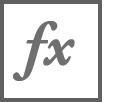`CheckAnnualEnergyConsumpion(annualEnergyConsumption)`

function CheckAnnualEnergyConsumpion(answer)
    arguments
       answer (1,1) sym 
    end

    % Compute the right answer
    load DataCenter.mat dataCenter
    rightAnswerUnit = str2symunit(dataCenter.Properties.VariableUnits);
    rightAnswer = sum(dataCenter.electricalConsumption)*rightAnswerUnit;
    
    if isequal(rightAnswer,answer)
        disp("Good job! You computed the total annual energy consumption correctly.")
    else
        warning("You can compute the total annual consumption by applying the 'sum' function"+...
            " to 'dataCenter.electricalConsumption'")
    end
end

`checkForceAirOnTurbine(answer)`

function checkForceAirOnTurbine(answer)
    arguments
        answer (1,1) sym
    end
    
    % Define the solution
    syms rho V_T S_T V_A V_B
    rightAnswer = rho*S_T*V_T*(V_A-V_B);
    
    if isequal(answer,rightAnswer)
        disp("Good job! The force acting on the turbine correctly!")
    elseif isequal(answer,-rightAnswer)
        warning("You have a sign error. Hint: the force acting on the turbine is the opposite"+...
            " of the force acting on the control volume.")
    else
        warning("The force acting on the turbine should be 'massFlow' multiplied by the "+...
            "velocity difference at disks A and B.")
    end

end

`checkPowerEquality(answer)`

function checkPowerEquality(answer)
arguments
    answer (1,1) sym
end
    answer = [rhs(answer); lhs(answer)];

    syms rho S_T V_T V_A V_B
    rightAnswer = S_T*V_T^2*rho*(V_A-V_B) == 0.5*rho*S_T*V_T*(V_A^2-V_B^2);
    rightAnswer = [rhs(rightAnswer); lhs(rightAnswer)];
    
    check = arrayfun(@isequal,rightAnswer,answer) | arrayfun(@isequal,rightAnswer,flip(answer));

    if all(check)
        disp("Good job! You defined the power equality correctly.")
    elseif check(1)
        warning("The equation’s left-hand side you entered in powerEquality is wrong.")
    elseif check(2)
        warning("The equation’s right-hand side you entered in powerEquality is wrong.")
    else
        warning("Hint: You can start by expressing the power at the turbine as in the "+...
            "previous section of the script.")
    end

end

`plotRetentionLake()`

function plotRetentionLake()
    Z = membrane(1,10);
    Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
    n = size(Z,1);
    [X,Y] = meshgrid(0:n-1,0:n-1);
    X = 2*X/(n-1) - 1;
    Y = 2*Y/(n-1) - 1;
    C = zeros(size(Z));
    C(11:31,11:31) = 1.0;
    Z(1,:) = 0.0;
    Z(end,:) = 0.0;
    Z(:,1) = 0.0;
    Z(1,end) = 0.0;
    Z( Z < 0 ) = 0.0;
    X = X * 100;
    Y = Y * 100;
    surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
    view([-64 59])
    mapFace = [0.3 0.3 0.3
               0.83 0.94 0.97];
    colormap(mapFace)
end

`checkElectricalConsumptionDimension(answer)`

function checkElectricalConsumptionDimension(answer)
arguments
    answer (1,1) 
end

    switch (answer)
        case 0
            warning("Please, select one of the option in the drop-down menu.")
        case 1
            disp("Good job! 'kWh' is indeed a unit of energy.")
        case 2
            warning("'kW' is a unit of power, so what would power (kW) times the unit"+...
                "of time (h) be?")
    end

end

`checkPowerTurbine(answer)`

function checkPowerTurbine(answer)
    arguments
        answer (1,1) sym
    end

    % Define the solution
    syms rho V_T S_T V_A V_B
    rightAnswer = rho*S_T*V_T^2*(V_A-V_B);

    if isequal(answer,rightAnswer)
        disp("Good job! You calculated the power at the turbine correctly.")
    else
        warning("Hint: the power collected should be the force 'F_T' from the previous"+...
            "exercise multiplied by the velocity at the turbine.")
    end
       
end

`checkVelocitySoln(answer)`

function checkVelocitySoln(answer)
    arguments
        answer (:,:) sym
    end

    syms S_T V_T rho V_A V_B
    eqn = S_T*V_T^2*rho*(V_A-V_B) == 0.5*rho*S_T*V_T*(V_A^2-V_B^2);
    rightAnswer = solve(eqn,V_T);

    if isequal(answer,rightAnswer)
        disp("Good job! You solve the equation correctly.")
    else
        warning("Hint: use the function solve!")
    end

end

`checkPowerTurbine2(answer)`

function checkPowerTurbine2(answer)
    arguments
        answer (1,1) sym
    end

    syms rho S_T V_A V_B
    rightAnwer = rho*S_T*(1/2*V_A+1/2*V_B)^2*(V_A-V_B);

    if isequal(answer,rightAnwer)
        disp("Good job! You found the expression of the power collected as a function"+...
            "of the upstream and downstream velocity.")
    else
        warning("Use the function 'subs' to replace V_T with the right component of solV_T.")
    end
end

`checkMaximumPower(answer)`

function checkMaximumPower(answer)
    arguments
        answer (1,1) sym
    end

    syms rho S_T V_A 
    rightAnswer = 1/2*S_T*rho*V_A^3;

    if isequal(answer,rightAnswer)
        disp("Good job! You defined the maximum to be collected by the turbine correctly.")
    elseif isequal(answer/2,rightAnswer)
        warning("You forgot to divide by 2.")
    elseif contains(string(answer),"V_T") || contains(string(answer),"V_B")
        warning("The maximum power is obtained when the velocity at the turbine is equal"+...
            " to the upstream velocity 'V_A'.")
    elseif contains(string(answer), "S_A") || contains(string(answer),"S_B")
        warning("The surface area of the turbine is unchanged here and should be equal 'S_T'.")
    else
        warning("The maximum power is obtained when the velocity at the turbine is equal"+...
            " to the upstream velocity 'V_A' and the surface of the turbine is 'S_T'.")
    end

end

`checkTurbineEta(answer)`

function checkTurbineEta(answer)
    arguments
        answer (1,1) sym
    end

    syms V_A V_B
    rightAnswer = 1/2*(V_A+V_B)^2*(V_A-V_B)/(V_A^3);
    answer = simplify(answer);
    
    if isequal(answer,rightAnswer)
        disp("Good job! You defined the turbine efficiency correctly.")
    else
        warning("Hint: The turbine efficiency is the ratio of the power collected by the"+...
            " turbine over the maximum power to be collected.")
    end
end

`checkAnnualRain(answer)`

function checkAnnualRain(answer)
    arguments
        answer (1,1) sym
    end

    if 0.99*6.7475e+08 <= separateUnits(answer) && separateUnits(answer) <= 1.01*6.7475e+08 
        disp("Good job! The mass of annual rain was defined correctly.")
    else
        warning("The mass of water can be computed with the density times the annual volume"+...
            " of water.")
    end

end

`checkSaturationPressure(answer)`

function checkSaturationPressure(answer)

    % Antoine's equation parameters:
    A = 8.07131;
    B = 1730.63;
    C = 233.426;
    load NatickWeather.mat weather

    rightAnswer = round(10.^(A-B./(C+weather.Temp)),4);
    wrong1 = round(A-B./(C+weather.Temp),4);
    wrong2 = round(A-B./C+weather.Temp,4);
    wrong3 = round(10.^(A-B./C+weather.Temp),4);
    answer = round(answer.saturationPressure,4);

    if isequal(rightAnswer,answer)
        disp("Good job! The saturation pressure was defined correctly.")
    elseif isequal(wrong1,answer)
        warning("Antoine's law describes the logarithm (base 10) of the saturation pressure"+...
            " you should have '10.^' in the expression for the saturation pressure.")
    elseif isequal(wrong2,answer)
        warning("Antoine's law describes the logarithm (base 10) of the saturation pressure"+...
            " you should have '10.^' in the expression for the saturation pressure. You might"+...
            " also have a problem with your syntax, check the parenthesis.")
    elseif isequal(wrong3,answer)
        warning("There is a problem with the syntax, check the parenthesis.")
    else
        warning("Use Antoine's law to compute the saturation pressure based on the temperature.")
    end
    
end

`checkWaterPressure(answer)`

function checkWaterPressure(answer)

    % Antoine's equation parameters:
    A = 8.07131;
    B = 1730.63;
    C = 233.426;
    load NatickWeather.mat weather
    Psat = 10.^(A-B./(C+weather.Temp));

    rightAsnwer = round(0.01*weather.RH.*Psat,4);
    answer = round(answer.waterPressure,4);
    wrong = round(weather.RH.*Psat,4);

    if isequal(answer,rightAsnwer)
        disp("Good job! The water pressure was defined correctly.")
    elseif isequal(answer,wrong)
        warning("The relative humidity is defined in percent, don't forget to divide by 100!")
    else
        warning("You can compute the water pressure based on the saturation pressure and"+...
            " the relative humidity.")
    end

end

`checkPowerExtractedTurbine(answer1,answer2)`

function checkPowerExtractedTurbine(answer1,answer2)
    
    units = symunit;
    eta = 0.4;
    rho = 1.2*units.kg/units.m^3;
    rightAnswer = eta/2*rho*pi/4*answer2^2*(answer1.Wind*units.m/units.s).^3;

    if isequal(sum(answer1.powerExtracted),sum(rightAnswer)) 
        disp("Good job! The power corrected was defined correctly.")
    else
        warning("You can compute the power extracted based on the wind speed and the"+...
            " expression developed in the previous section of this script.")
    end
end

[⇦ Return to the navigation page](matlab:open('./Navigation.mlx'))

Copyright 2023 The MathWorks™, Inc